Since 20220727, I have been doing simulation of FLP with modified version (like change the population of 256 channels to 512 channels, detailed changes see the script /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220727.mlx). And for the results of the threshold of photon counts, I've seen very different results. To figure out why it's the case, I need to just change one thing at a time to figure out why it's causing all these difference. This time I'm using the same tau1 and tau2, same autofluorescence, DC, and afterpulse for the simulation, basically repeat the simulation of /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220326.mlx with just different tau1 and tau2.

% give this simulation a name
SimulationName='simulation_ACh_20220806';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220806/'

cd(filepath)

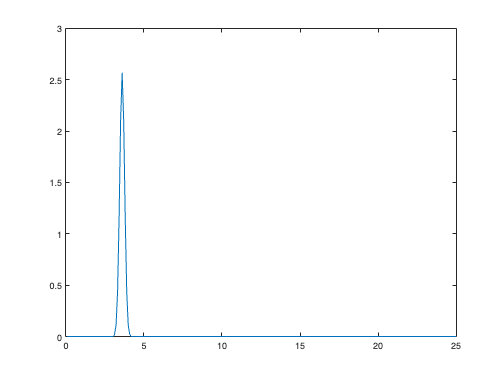

% guassian fitting curve, used what's from before
width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

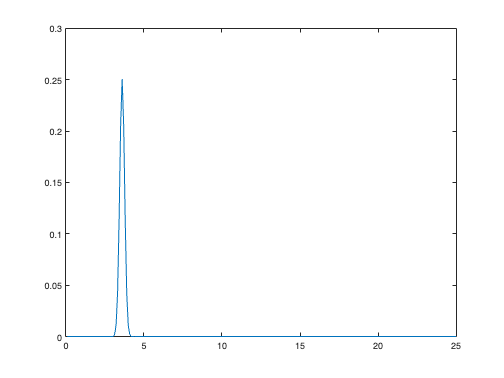

Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)

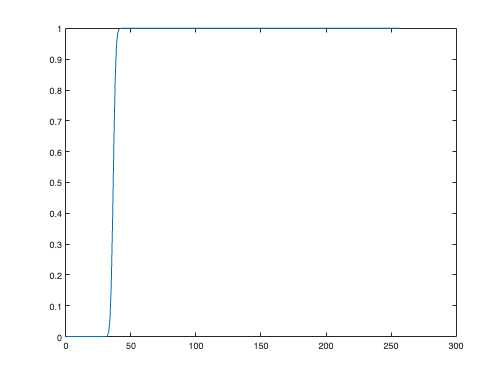


Gaussian_y=Gaussian_y';


cumulative_prf=cumsum(Gaussian_y);
figure
plot(cumulative_prf)


PrfName='prf_gaussian.mat';
save(PrfName,'Gaussian_y')

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.6199; % 
tau2=0.9221;
DC=0;
afterpulse_ratio=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.


% This is the content of the script for batch processing.
% for i=1:21
    rng('shuffle','twister')
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=[SimulationName,'_FLP_population_',num2str(p1),'.mat'];
    GenPop512_FLP(100000, p1, p2, tau1, tau2, PopulationName); 
    for j=1:25
        SS=SS_samples(j);
        afterpulse=afterpulse_ratio*SS;
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim512_FLP(SS,DC,afterpulse,PrfName, PopulationName,samplename)
        end
    end
% end


c=parcluster()

for i=1:21

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/mapingchuan/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

    batch('FLP_simulation_batch2')
end

ans = 

 Job

    Properties: 

                   ID: 1
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:17:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 2
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:17:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 3
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:01
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 4
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 5
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:08
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 6
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 7
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:15
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 8
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:18
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 9
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 10
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:26
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 11
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:31
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 12
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 13
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 14
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:45
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 15
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:51
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 16
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:18:56
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 17
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:19:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 18
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:19:11
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 19
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:19:21
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 20
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:19:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 21
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 13:19:40
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

cd('/Users/pingchuanma/Desktop/ChenLab_Data/some raw data/20220208_PM13_autofluo_001')

filename='PM13_autofluo_20220208.mat';
load(filename)
autofluorescence_FLP=mean(lifetime_histograms');

cd(filepath)
sum(autofluorescence_FLP)

ans = 2.0931e+04

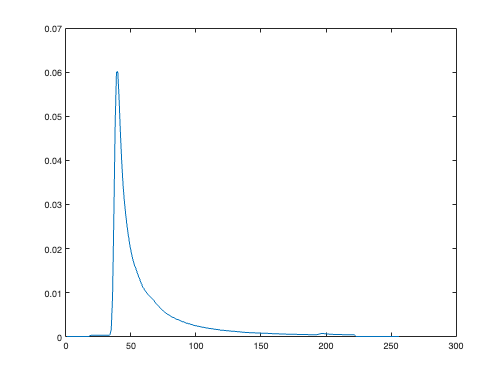

Autofluorescence_file='Autofluorescence_PM13.mat';
autofluo=autofluorescence_FLP/sum(autofluorescence_FLP);
figure
plot(autofluo)

save(Autofluorescence_file,'autofluo')


filepath = '/Users/mapingchuan/Desktop/ChenLab_Data/simulation_ACh_20220804_2/'

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/mapingchuan/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

ans = 

 Job

    Properties: 

                   ID: 43
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 05-Aug-2022 00:53:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

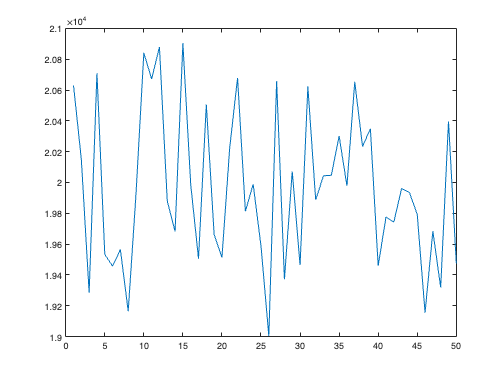

AF_mean=20000;
AF_all=zeros(1,50);


mkdir([num2str(AF_mean),'_AF'])
for i=1:50
    AF=randi(2000)+19000; % 10% of fluctuation
    AF_all(i)=AF;
    samplename=[num2str(AF_mean),'_AF/',num2str(i),'_auto.mat'];
    AutoFluo_sim(Autofluorescence_file, AF, samplename)
end

figure
plot(AF_all)

range=[22 190]

range =     22   190


empirical_lft_analytical_all=[];
peaks=[];
for i=1:21
    p1=p1_samples(i);
    PopulationName=[SimulationName,'_FLP_population_',num2str(p1),'.mat'];
    load(PopulationName)
%     figure
%     semilogy(counts)
    conv_n=conv(counts,Gaussian_y);
%     figure
%     semilogy(conv_n)
    conv_n1=conv_n(257:512);
    conv_n_final=conv_n(1:256)+conv_n1; % wrap around
%     figure
%     semilogy(conv_n_final)

    lft_steps=(1:1:169)*25/256;
    weight_n_lft=lft_steps.*conv_n_final(range(1):range(2));
    empirical_lft=sum(weight_n_lft)/sum(conv_n_final(range(1):range(2)));
    empirical_lft_analytical_all=[empirical_lft_analytical_all empirical_lft];

    peak=find(conv_n_final==max(conv_n_final));
    peaks=[peaks peak];
end

ch=1;
for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);

        tau_empTrunc=[];
        photoncount=[];
        
        for k=1:50
            
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n;
            lft_steps=(1:1:169)*25/256;
            weight_n_lft=lft_steps.*n_ACh(range(1):range(2)); 
            tau_empTrunc(k)=sum(weight_n_lft)/sum(n_ACh(range(1):range(2)));
            photoncount(k)=sum(n_ACh);

        end
       
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result.mat'];
        save(result_name,'photoncount', 'tau_empTrunc')
    end
end

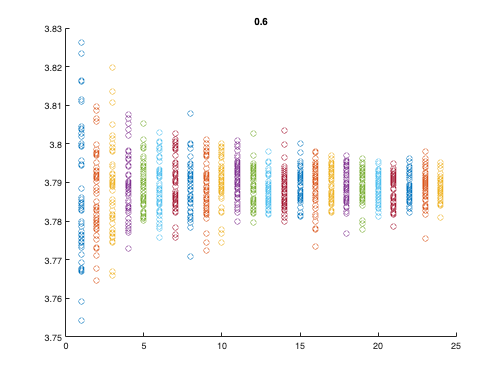

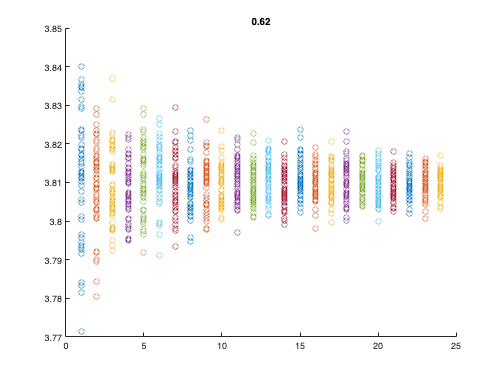

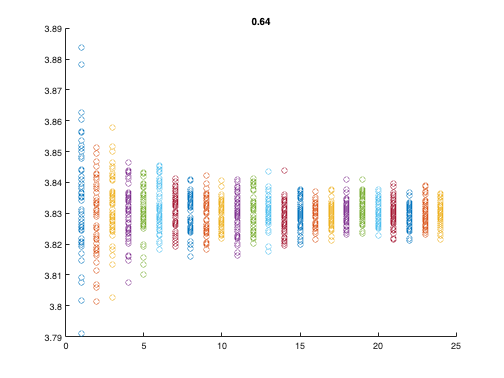

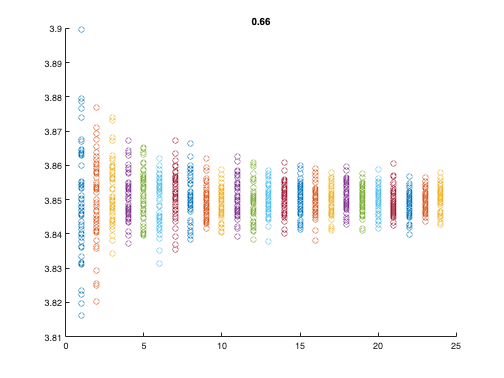

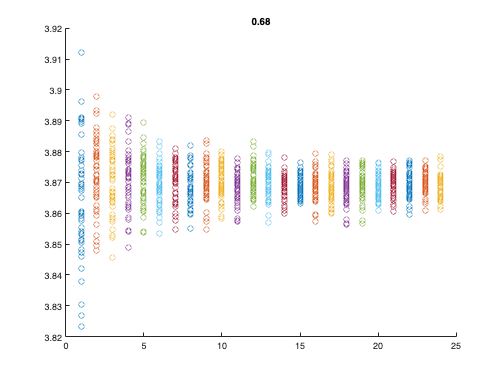

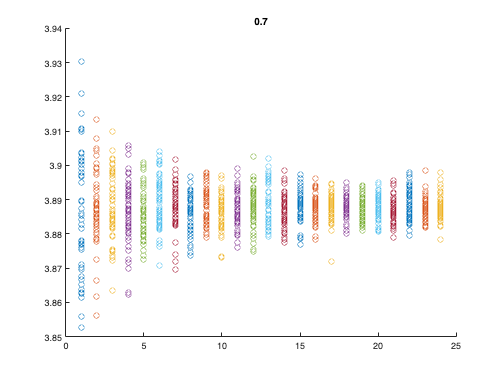

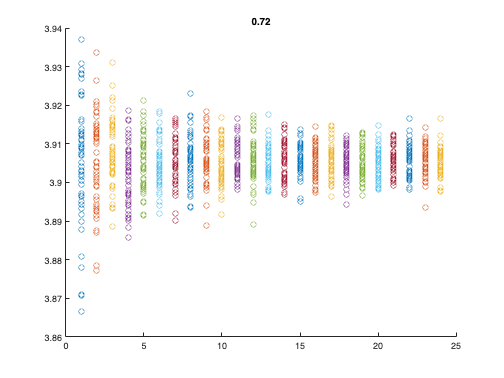

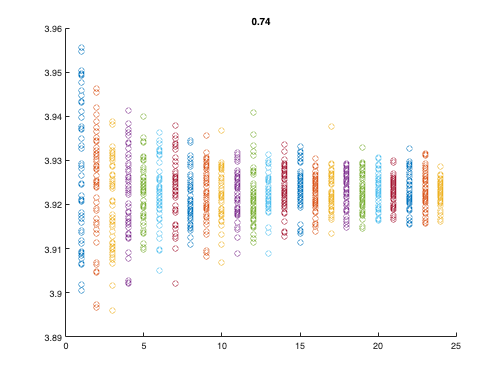

% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the p1 conditions
for i=1:21
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    figure

    for j=1:25
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),'; tau_empTrunc];'])
        scatter((zeros(1,50)+j),tau_empTrunc)
        hold on
    end
    title(num2str(p1))
    hold off
end

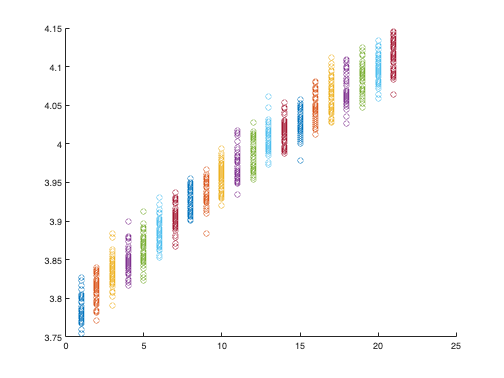

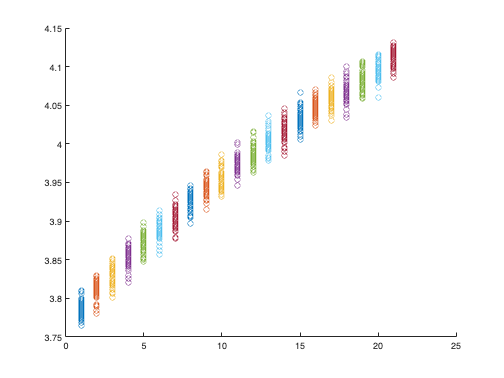

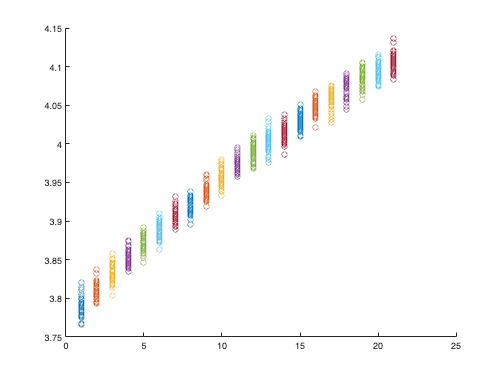

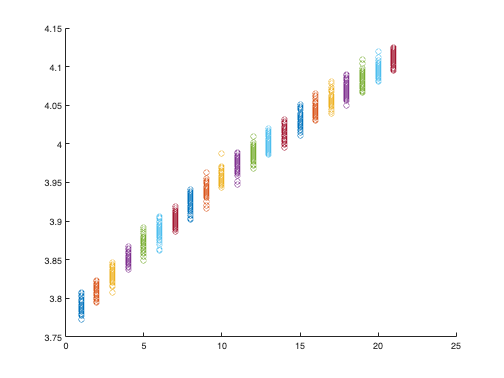

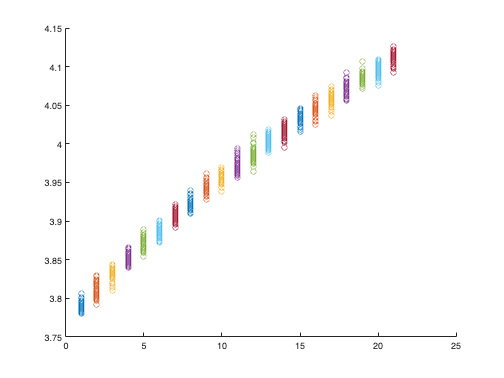

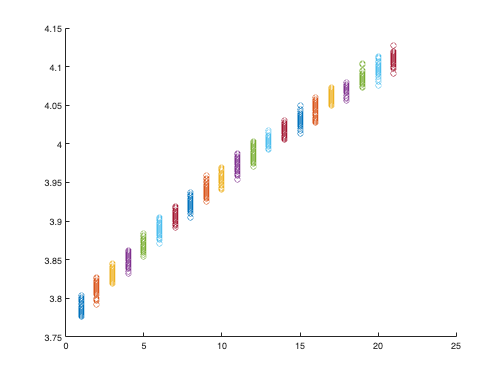

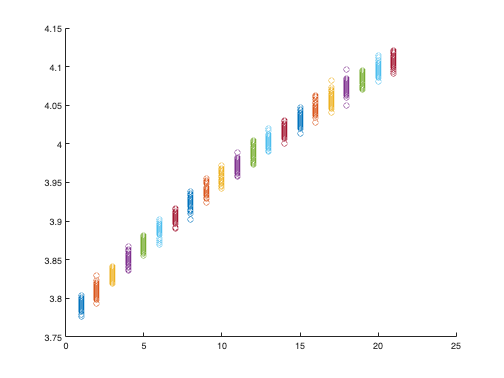

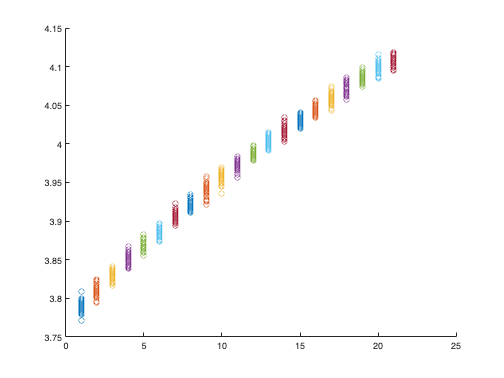

% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the sample size conditions

for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    eval(['tau_empTrunc_mean_',num2str(SS),'=[];'])
    figure
    title(num2str(SS))
    for i=1:21
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),'; tau_empTrunc];'])
        eval(['tau_empTrunc_mean_',num2str(SS),'=[tau_empTrunc_',num2str(SS),'; tau_empTrunc];'])
        scatter((zeros(1,50)+i),tau_empTrunc)
        hold on
    end
%     plot(1:1:21,empirical_lft_analytical_all)
    hold off
end

std_all=[];
mean_all=[]; % both of them will be a 25 x 21 matrix; row represents photon count and column represents p1

for i=1:25
    SS=SS_samples(i);
    eval(['this_samplesize=transpose(tau_empTrunc_',num2str(SS),');'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end

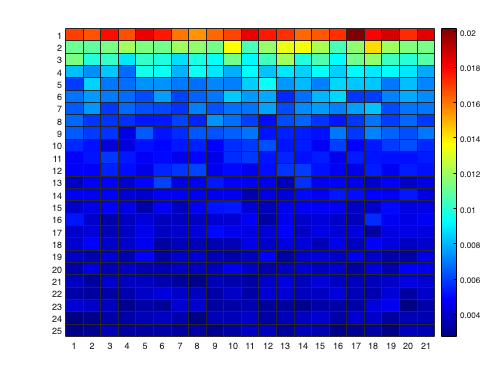

% plot the heatmap of mean and std of each condition
figure
h1=heatmap(std_all);
colormap jet;

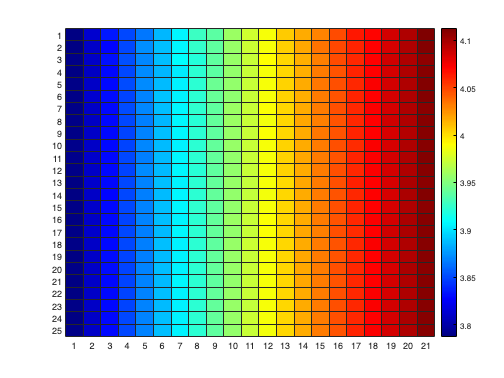

figure
h2=heatmap(mean_all);
colormap jet;

ch=1;
for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);

        tau_empTrunc=[];
        photoncount=[];
        
        for k=1:50
            
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n;

            AutoFluoName=['20000_AF/',num2str(k),'_auto.mat'];
            load(AutoFluoName)
            

            n1=n_ACh+n_auto;

            lft_steps=(1:1:169)*25/256;
            weight_n_lft=lft_steps.*n1(range(1):range(2)); 
            tau_empTrunc(k)=sum(weight_n_lft)/sum(n1(range(1):range(2)));
            photoncount(k)=sum(n1);

        end
       
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result2.mat']; % result2, ACh+DC+afterpulse+autofluo
        save(result_name,'photoncount', 'tau_empTrunc')
    end
end

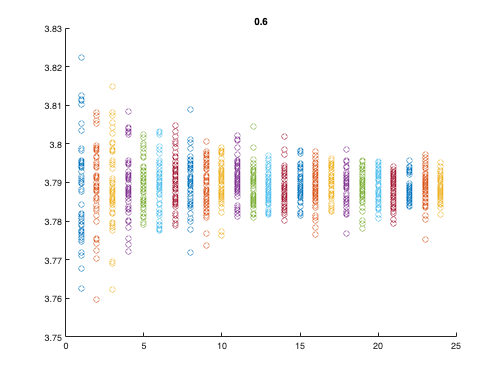

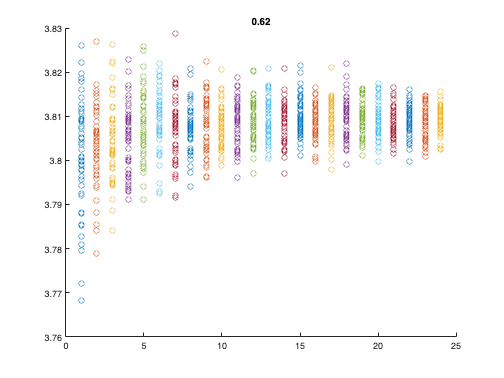

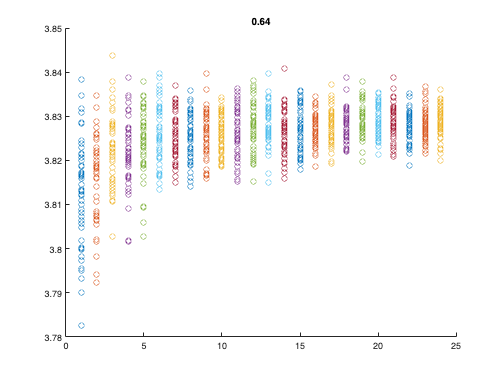

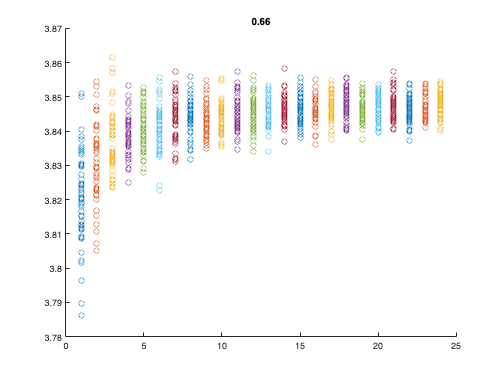

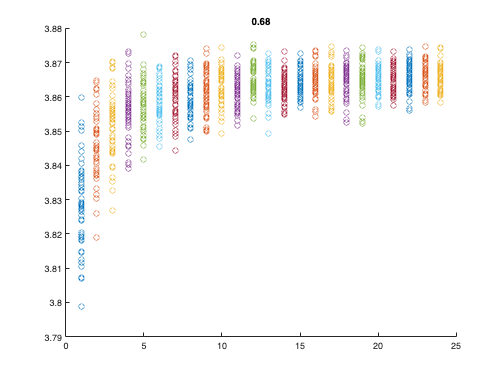

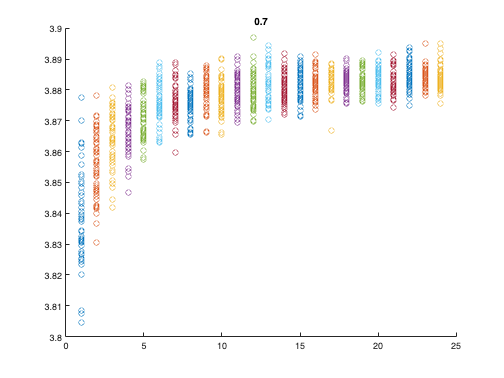

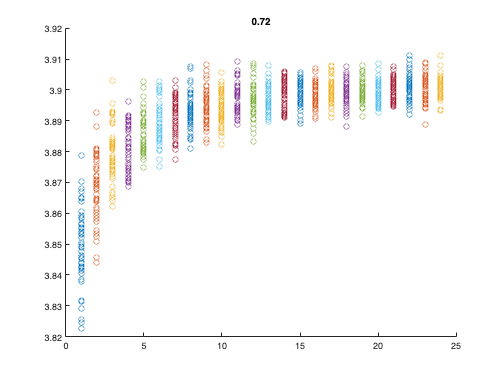

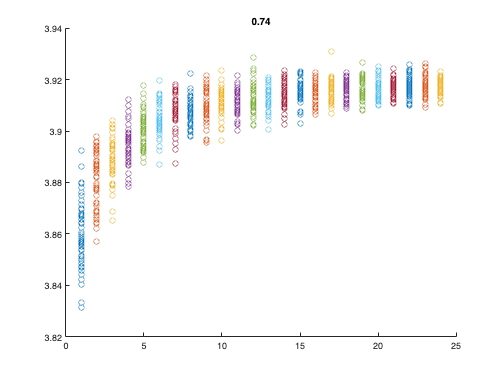

% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the p1 conditions
for i=1:21
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    figure

    for j=1:25
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result2.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),'; tau_empTrunc];'])
        scatter((zeros(1,50)+j),tau_empTrunc)
        hold on
    end
    title(num2str(p1))
    hold off
end

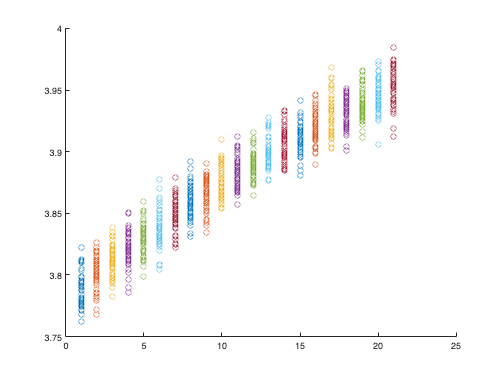

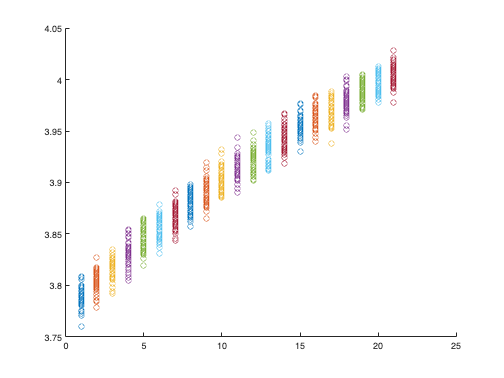

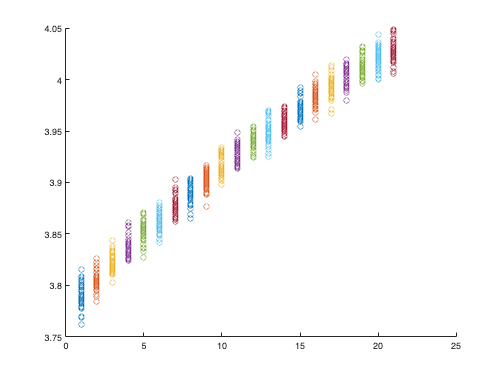

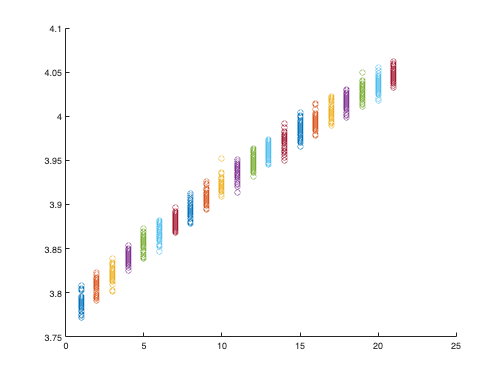

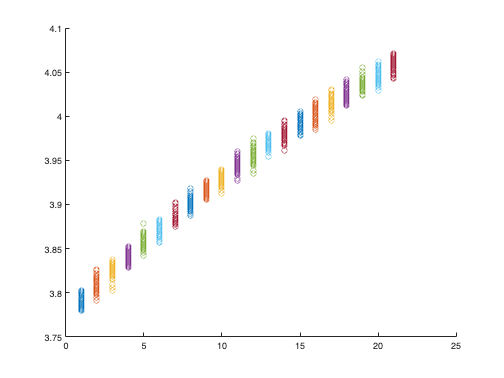

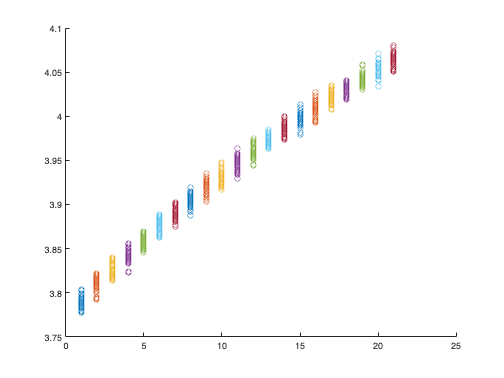

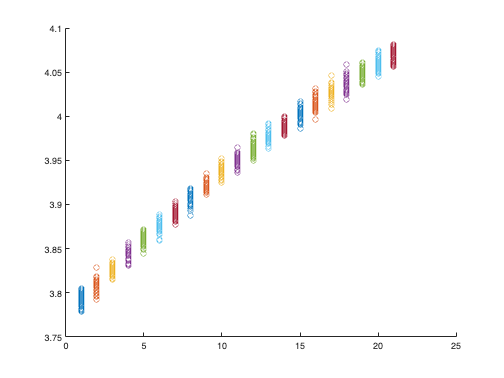

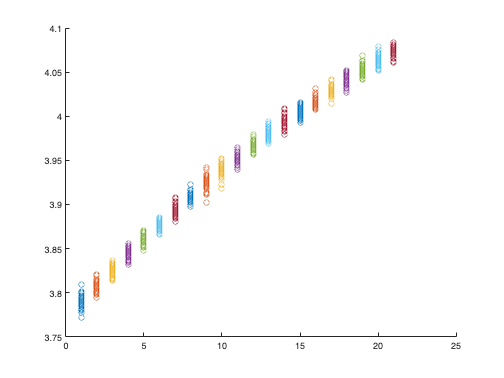

% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the sample size conditions

for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    eval(['tau_empTrunc_mean_',num2str(SS),'=[];'])
    figure
    title(num2str(SS))
    for i=1:21
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_empirical_result2.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),'; tau_empTrunc];'])
        eval(['tau_empTrunc_mean_',num2str(SS),'=[tau_empTrunc_',num2str(SS),'; tau_empTrunc];'])
        scatter((zeros(1,50)+i),tau_empTrunc)
        hold on
    end
%     plot(1:1:21,empirical_lft_analytical_all)
    hold off
end

std_all=[];
mean_all=[]; % both of them will be a 25 x 21 matrix; row represents photon count and column represents p1

for i=1:25
    SS=SS_samples(i);
    eval(['this_samplesize=transpose(tau_empTrunc_',num2str(SS),');'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end

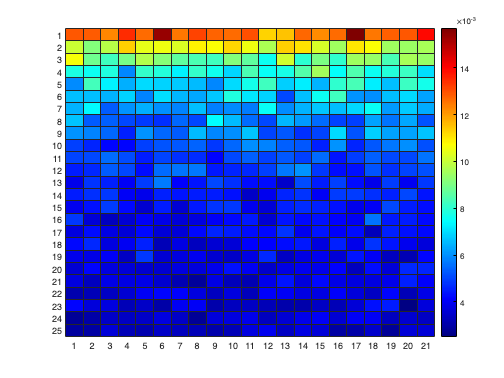

% plot the heatmap of mean and std of each condition
figure
h1=heatmap(std_all);
colormap jet;

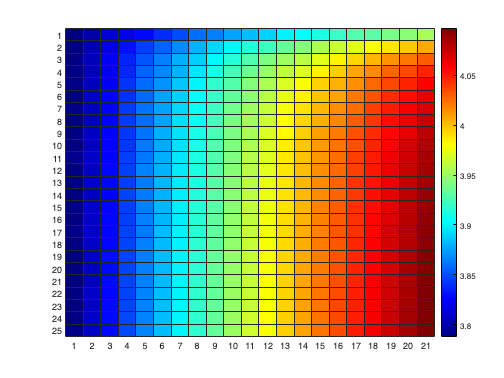

figure
h2=heatmap(mean_all);
colormap jet;